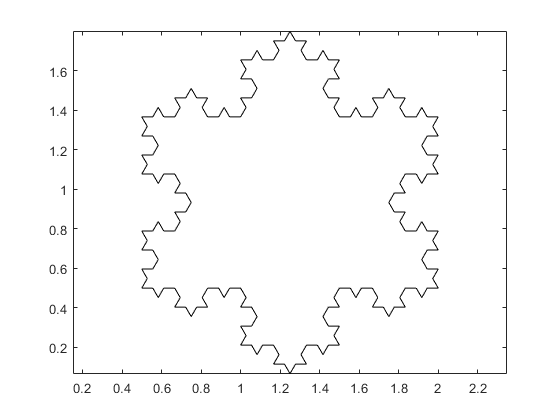

clc;
clear;
% 通过复数曲线绘制Koch雪花
x_n=[1 (1+sqrt(3)*1i)/2 0 1];
slice=3; %这里是迭代次数
for n=1:slice
    x_p=x_n;
    lastSeg=length(x_n)-1;
    for k=0:lastSeg-1
        dX=(x_p(k+2)-x_p(k+1))/3;x_n(4*k+1)=x_p(k+1);
        x_n(4*k+2)=x_p(k+1)+dX;
        x_n(4*k+3)=x_n(4*k+2)+dX*(1/2-sqrt(3)*1i/2);
        x_n(4*k+4)=x_p(k+1)+2*dX;
    end
    x_n(4*lastSeg+1)=x_p(lastSeg+1);
end
x_n=1.5*x_n+0.5+0.5*1i;
plot(x_n,'k'),hold on;
axis equal;

x_koch=real(x_n);
y_koch=imag(x_n);

%生成矩形天线阵列
N1=50;
N2=50;
f0=3e9;
c=3e8;
lambda=c/f0; 
dx=lambda/2;
dy=lambda/2;
k=2*pi/lambda;

phi=0*pi/180;%目标方位角
theta=0*pi/180;%目标俯仰角

theta1=sin(phi)*cos(theta)

theta1 = 0

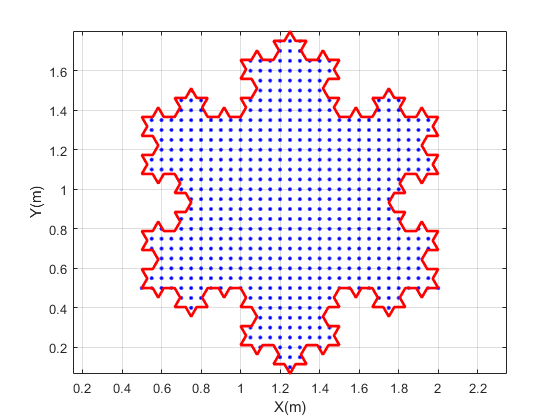

theta2=sin(theta);

X=[0:(N1-1)]*dx;
Y=[0:(N2-1)]*dy;
X2=kron(ones(1,N2),X);
Y2=kron(Y,ones(1,N1));

%去掉雪花外的天线
[~,n]=size(X2);
index=1;
while(index<=n)
    if ~inpolygon(X2(index),Y2(index),x_koch,y_koch)
        X2=dele(X2,index);
        Y2=dele(Y2,index);
        n=n-1;
        index=index-1;
    end
    index=index+1;
end

%绘图
figure
plot(X2,Y2,'b.','markersize',8);
hold on
plot(x_koch,y_koch,'r','linewidth',2);
axis equal;
grid on;
xlabel('X(m)');
ylabel('Y(m)');

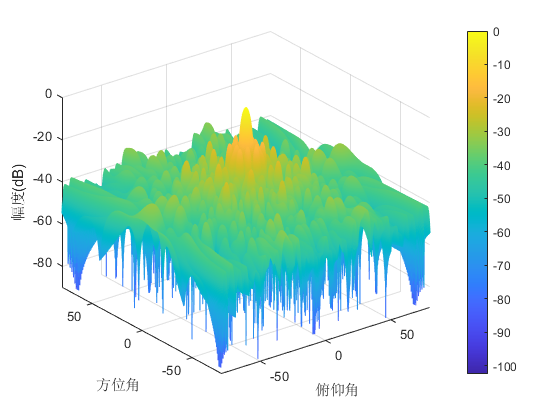

steer_signal1=exp(1j*k*X2*theta1);
steer_signal2=exp(1j*(k*Y2*theta2));
steer_signal3=steer_signal1.*steer_signal2;
normal_W=steer_signal3;
%合成方向图
Theta =-80:0.1:80;
Phi =-80:0.1:80;
m = length (Theta);
n = length (Phi);
F = zeros (m,n);
for m =1:length(Theta)
    for n =1:length(Phi)
         theta =Theta(m); 
         phi = Phi(n);
         phase1 = exp(1j*k*X2*sin(theta*pi/180)*cos(phi*pi/180));
         phase2 = exp(1j*k*Y2*sin(phi*pi/180));
         phase_all = (phase1.*phase2).';
         F(m,n)=abs(((normal_W.')')*phase_all);
    end
end
FdB =20*log10(F/max(max(F)));%画增益图
figure 
mesh(Phi,Theta,FdB); 
colorbar 
xlabel ('俯仰角'); 
ylabel ('方位角'); 
zlabel ('幅度(dB)'); 
axis ([-80 80 -80 80 -90 0]);

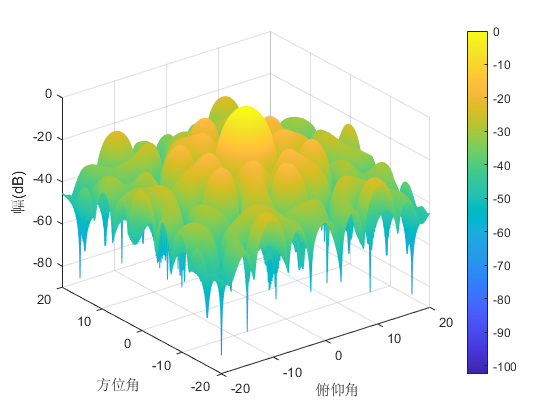

%画增益图放大
figure
mesh (Phi, Theta, FdB) ;
xlabel('俯仰角');ylabel( '方位角');zlabel( '幅(dB)');
  axis([-20 20 -20 20 -90 0]);
colorbar

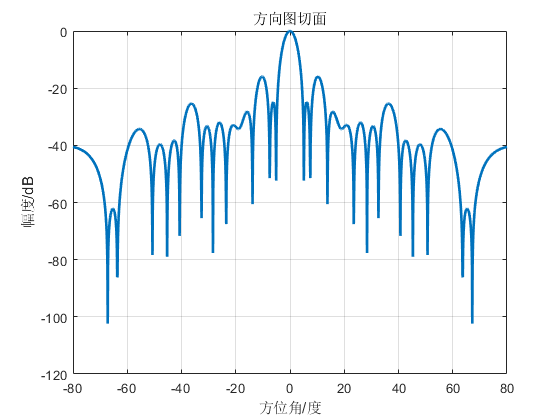

%画方位增益图
[ymax, iy]=max(max(FdB)); 
figure
plot (Theta,FdB(:,iy),'linewidth',2);title('方向图切面');
xlabel('方位角/度');ylabel( '幅度/dB')
grid on;
hold on

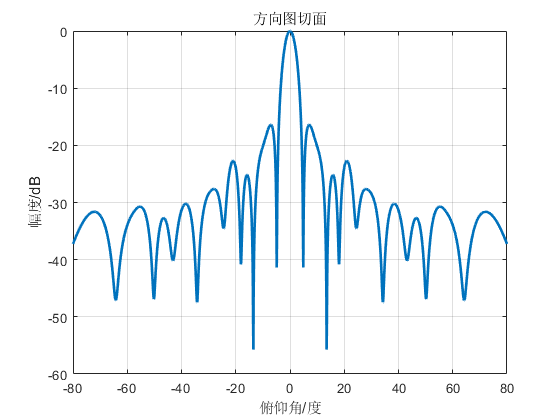

%画俯仰增益图
[xnax,ix]=max(FdB(:,iy));
figure
plot(Phi,FdB(ix, :),'linewidth',2);title('方向图切面');
xlabel( '俯仰角/度');ylabel( '幅度/dB');grid on;hold on;

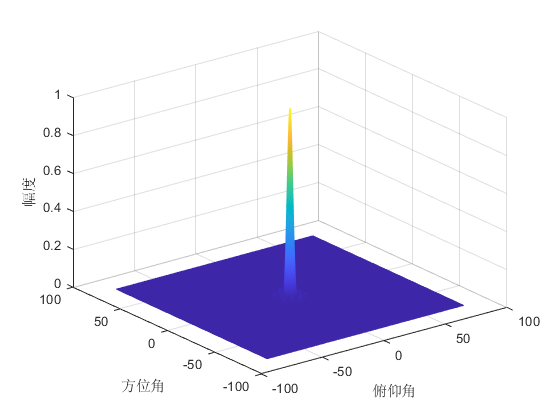

%画方位原始数值增益
figure
mesh(Phi, Theta, 10.^(FdB/10));
xlabel( '俯仰角');ylabel( '方位角');zlabel( '幅度')